% butterworth LPF IIR
clc
clear all
close all
wp=input('enter pass band frequency: ')

wp = 1000

ws=input('enter stop band frequency: ')

ws = 2000

deltap=input('enter pass band ripple: ')

deltap = 3

deltas=input('enter stop band ripple: ')

deltas = 4

fs=10000

fs = 10000

omegap=2*tan(2*wp/fs)/sqrt(1+tan(2*wp/fs)^2)

omegap = 0.3973

omegas=2*tan(2*ws/fs)/sqrt(1+tan(2*ws/fs)^2)

omegas = 0.7788

delta=min(1/deltap^2-1,1/deltas^2-1)

delta = -0.9375

del=1/deltap^2-1

del = -0.8889

num=2*log10(delta/del)

num = 0.0462

den=log10(omegas/omegap)

den = 0.2923

order=ceil(num/den)

order = 1

fc=1000

fc = 1000

[b,a]=butter(order,fc/(fs/2),'low')

b =     0.2452    0.2452


a =     1.0000   -0.5095


freqz(b,a,1000)
f1=500

f1 = 500

f2=2000

f2 = 2000

N=200

N = 200

t=0:N-1

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


x=sin(2*pi*f1*t/fs)+2*sin(2*pi*f2*t/fs)

x =          0    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931   -0.0000    1.5931    0.5878   -1.9846   -2.8532   -1.0000    0.9511    0.3666   -1.7634   -2.2111   -0.0000    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931   -0.0000    1.5931    0.5878   -1.9846   -2.8532   -1.0000    0.9511    0.3666   -1.7634   -2.2111   -0.0000    2.2111    1.7634   -0.3666   -0.9511    1.0000    2.8532    1.9846   -0.5878   -1.5931


xf=abs(fft(x))/N

xf =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.5000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


two_pow=xf.*xf

two_pow =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.2500    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


f=(0:N-1)*fs/N

f =            0          50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400        1450        1500        1550        1600        1650        1700        1750        1800        1850        1900        1950        2000        2050        2100        2150        2200        2250        2300        2350        2400        2450


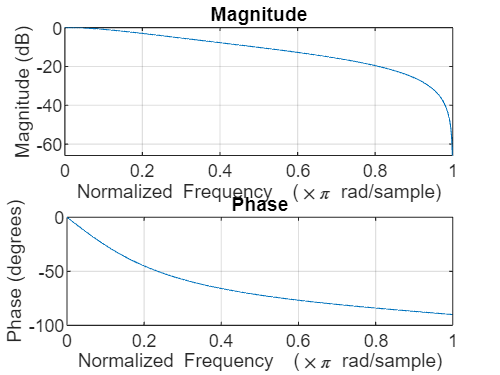

subplot(2,1,1)

plot(f,two_pow)
fil_sgnl=filter(b,a,two_pow)

fil_sgnl =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0613    0.0925    0.0472    0.0240    0.0122    0.0062    0.0032    0.0016    0.0008    0.0004    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.2452    0.3702    0.1886    0.0961    0.0490    0.0250    0.0127    0.0065    0.0033    0.0017


xf_fil=abs(fft(fil_sgnl))/N

xf_fil =     0.0125    0.0055    0.0060    0.0066    0.0038    0.0097    0.0022    0.0091    0.0094    0.0007    0.0067    0.0006    0.0087    0.0081    0.0019    0.0080    0.0030    0.0051    0.0045    0.0040    0.0088    0.0038    0.0041    0.0043    0.0024    0.0062    0.0014    0.0056    0.0057    0.0004    0.0040    0.0004    0.0051    0.0047    0.0011    0.0047    0.0018    0.0029    0.0026    0.0023    0.0051    0.0022    0.0023    0.0025    0.0014    0.0036    0.0008    0.0032    0.0033    0.0002


two_power=xf_fil.*xf_fil

two_power = 1.0e-03 *

    0.1562    0.0298    0.0365    0.0430    0.0144    0.0944    0.0049    0.0820    0.0889    0.0004    0.0454    0.0004    0.0761    0.0650    0.0036    0.0647    0.0092    0.0257    0.0205    0.0158    0.0781    0.0142    0.0165    0.0186    0.0060    0.0381    0.0019    0.0312    0.0330    0.0002    0.0163    0.0001    0.0265    0.0224    0.0012    0.0219    0.0031    0.0086    0.0069    0.0053    0.0260    0.0047    0.0055    0.0062    0.0020    0.0126    0.0006    0.0103    0.0109    0.0001


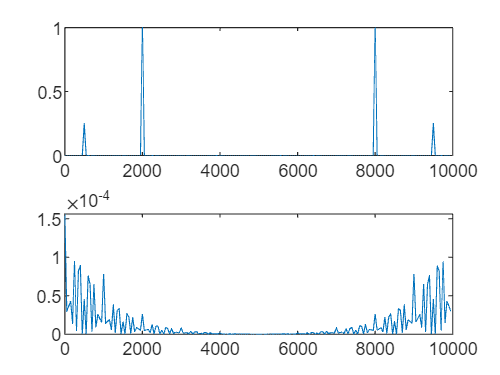

subplot(2,1,2)
plot(f,two_power)

clc
clear all
close all
wp=input('enter pass band frequency: ')

wp = 1000

ws=input('enter stop band frequency: ')

ws = 2000

deltap=input('pass band ripple: ')

deltap = 2

deltas=input('enter stop band ripple: ')

deltas = 3

fs=10000

fs = 10000

omegap=2*tan(2*wp/fs)/sqrt(1+tan(2*wp/fs)^2)

omegap = 0.3973

omegas=2*tan(2*ws/fs)/sqrt(1+tan(2*ws/fs)^2)

omegas = 0.7788

delta=min(1/deltap^2-1,1/deltas^2-1)

delta = -0.8889

del=1/deltap^2-1

del = -0.7500

num=2*log10(delta/del)

num = 0.1476

den=log10(omegas/omegap)

den = 0.2923

fc=1000

fc = 1000

order=ceil(num/den)

order = 1

[b,a]=butter(order,fc/(fs/2),'high')

b =     0.7548   -0.7548


a =     1.0000   -0.5095


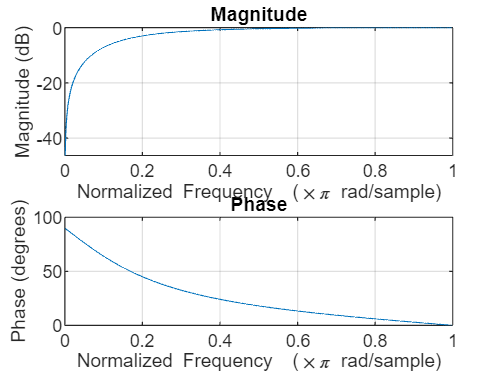

freqz(b,a,1000)

clc
clear all
close all
wp=input('enter pass band frequency: ')

wp = 1000

ws=input('enter stop band frequency: ')

ws = 2000

wp1=input('enter pass band freq-1: ')

wp1 = 3000

ws1=input('enter stop band freq-1: ')

ws1 = 5000

deltap=input('pass band ripple: ')

deltap = 2

deltas=input('enter stop band ripple: ')

deltas = 3

fs=10000

fs = 10000

delta=min(1/deltap^2-1,1/deltas^2-1)

delta = -0.8889

del=1/deltap^2-1

del = -0.7500

omegap=2*tan(wp*2/fs)/sqrt(1+tan(wp*2/fs)^2)

omegap = 0.3973

omegas=2*tan(2*ws/fs)/sqrt(1+tan(2*ws/fs)^2)

omegas = 0.7788

omegap1=2*tan(wp1*2/fs)/sqrt(1+tan(wp1*2/fs)^2)

omegap1 = 1.1293

omegas1=2*tan(2*ws1/fs)/sqrt(1+tan(2*ws1/fs)^2)

omegas1 = 1.6829

den=log10(omegas*omegas1/omegap*omegap1)

den = 0.5712

num=2*log10(delta/del)

num = 0.1476

fc=1000

fc = 1000

order=ceil(num/den)

order = 1

[b,a]=butter(order,[omegap,omegap1]/(fs/2),'bandpass')

b = 1.0e-03 *

    0.2299         0   -0.2299


a =     1.0000   -1.9995    0.9995


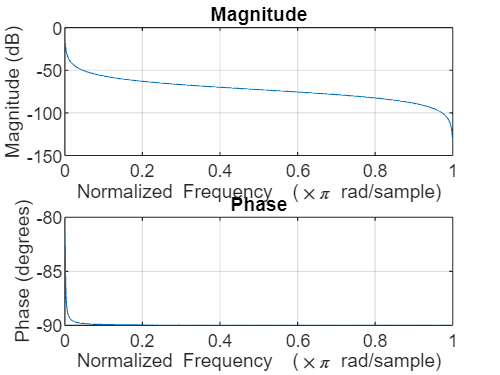

freqz(b,a,1000)

wp = 1000

ws = 3000

wp1 = 4000

ws1 = 7000

deltap = 2

deltas = 3

fs = 10000

omegap = 0.3973

omegas = 1.1293

omegap1 = 1.4347

omegas1 = 1.9709

delta = -0.8889

del = -0.7500

num = 0.1476

den = 0.9051

order = 1

b =     1.0003   -2.0007    1.0003


a =     1.0000   -2.0007    1.0007


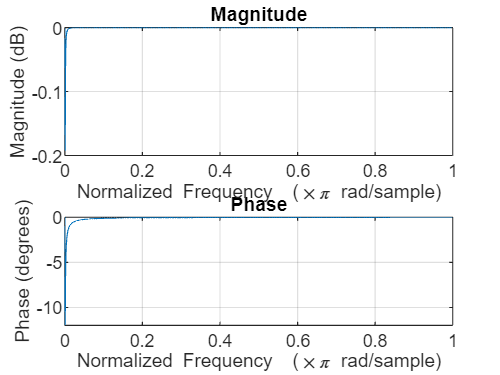

clc

clear all
close all
wp=input('enter pass band freq: ')
ws=input('enter stop band freq: ')
wp1=input('enter pass band freq-1 ')
ws1=input('enter stop band freq-2 ')
deltap=input('enter pass band ripple: ')
deltas=input('enter stop band ripple: ')
fs=10000
omegap=2*tan(2*wp/fs)/sqrt(1+tan(2*wp/fs)^2)
omegas=2*tan(2*ws/fs)/sqrt(1+tan(2*ws/fs)^2)
omegap1=2*tan(2*wp1/fs)/sqrt(1+tan(2*wp1/fs)^2)
omegas1=2*tan(2*ws1/fs)/sqrt(1+tan(2*ws1/fs)^2)
delta=min(1/deltap^2-1,1/deltas^2-1)
del=1/deltap^2-1
num=2*log10(delta/del)
den=log10(omegas*omegas1/omegap*omegap1)
order=ceil(num/den)
[b,a]=butter(order,[omegap1 omegap]/(fs/2),'stop')
freqz(b,a,1000)
